# 5G NR Waveform Capture and Analysis Using Software-Defined Radio

This example shows how to use the [**5G Waveform Generator**](docid:5g_ref#mw_ebf1de3e-8ad4-43f1-8f16-045653b47850) app to generate and transmit a standard-compliant 5G NR waveform continuously over the air using a software-defined radio (SDR). The example then shows how to capture the transmitted waveform from the air using an SDR and analyze the signal in MATLAB®.

## Introduction

This diagram shows the main steps of the example. 

- Generate a baseband waveform by using the **5G Waveform Generator** app.

- Transmit the generated waveform over the air, directly from the app, by using a connected SDR hardware (requires an SDR support package).

- Capture the over-the-air waveform in MATLAB by using another connected SDR hardware or the same SDR hardware (requires an SDR support package). 

- Analyze the PDCCH/PDSCH error vector magnitude (EVM) of the captured waveform in MATLAB.

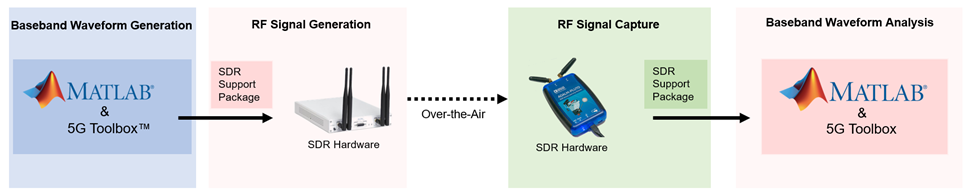

To transmit and capture waveforms with SDRs, you must install the corresponding hardware support package. This list provides information on which radios can be used by this example along with the required products. 

- ADALM-PLUTO (requires Communications Toolbox Support Package for Analog Devices® ADALM-PLUTO Radio). For more information, see [ADALM-Pluto Radio](docid:comm_doccenter#mw_0e7ad01a-dc12-4f4d-bd42-54dc112c2e1d).

- 200-series USRP™ radio (requires Communications Toolbox Support Package for USRP™ Radio). For more information, see [USRP Radio](docid:comm_doccenter#mw_de5fc03d-bc6e-471f-8da6-5e93b9b65012) and [Supported Hardware and Required Software](docid:usrpradio_ug#buzc7a6-1).

- 300-series USRP radio (requires Wireless Testbench Support Package for NI USRP Radios). For information on how to map an NI USRP device to an Ettus Research 300-series USRP device, see [Supported Radio Devices](docid:wt_gs#mw_74eb94c7-dcbc-40dc-8a56-cc7bc0124002).

- USRP™ E310/E312 (requires Communications Toolbox Support Package for USRP™ Embedded Series Radio). For more information, see [USRP Embedded Series Radio](docid:comm_doccenter#mw_eaac0336-4b33-4e96-9c62-3fe07bf7e726).

- AD936x/FMCOMMS5 radio (requires SoC Blockset Support Package for Xilinx Devices). For more information, see [Xilinx Devices](docid:soc_doccenter#xilinx_spkg).

If you are using a 200-series or 300-series USRP radio, you must receive the transmitted signal using a second SDR and MATLAB session.

## Generate Baseband Waveform

In MATLAB, on the **Apps** tab, click the **5G Waveform Generator** app.

In the **Waveform Type** section, click **Downlink FRC**. In the leftmost pane of the app, you can set the parameters for the selected waveform. For this example:

- Set **Frequency range** to `FR1 (410 MHz - 7.125 GHz)`.

- Set **MCS** to `64QAM, R=3/4`.

- Set **Subcarrier spacing (kHz)** to `30`.

- Set **Channel bandwidth (MHz)** to `10`.

- Set **Duplex mode** to `FDD`.

- Set **RNTI** to 0.

- Select the **OCNG** check box.

On the app toolstrip, click** Generate**.

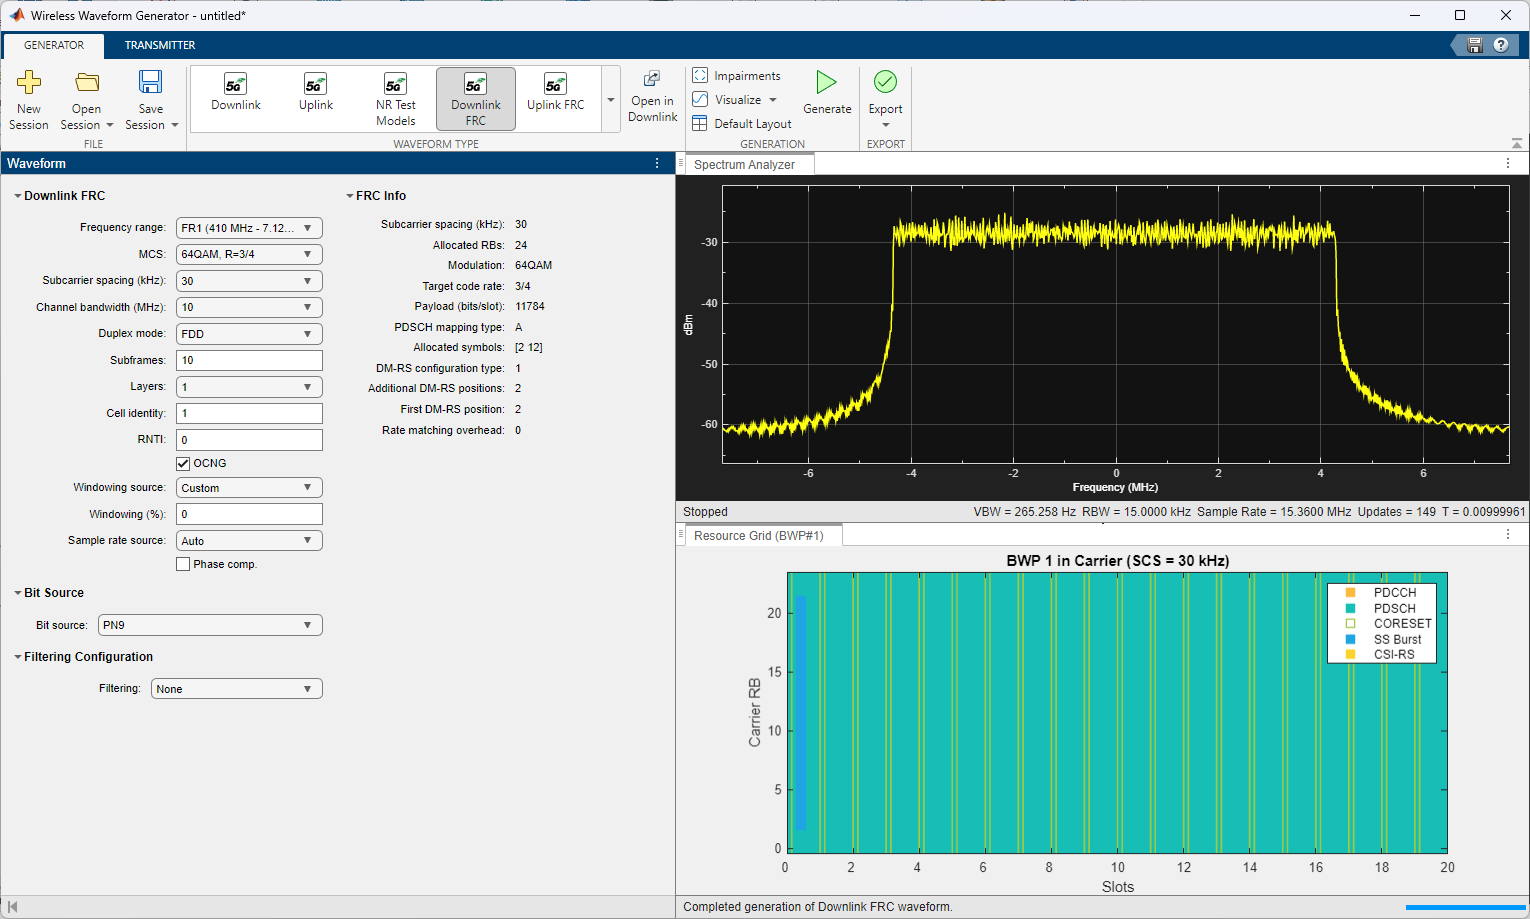

## Transmit Generated Waveform

On the **Transmitter** tab of the app, in the **Transmitter Type** section, select your SDR for waveform transmission.

- If you have an ADALM-PLUTO radio corresponding to the Communications Toolbox Support Package for Analog Devices ADALM-PLUTO Radio, select `Pluto`.

- If you have a USRP E310 or E312 radio corresponding to the Communications Toolbox Support Package for USRP Embedded Series Radio, select `USRP E`.

- If you have a AD936x or FMCOMMS5 radio corresponding to the SoC Blockset Support Package for Xilinx Devices, select `Zynq Based`.

- If you have a USRP 200-series radio corresponding to the Communications Toolbox Support Package for USRP Radio, select `USRP B/N/X`.

- If you have a USRP 300-series radio corresponding to the Wireless Testbench Support Package for NI USRP Radios, select `USRP B/N/X`.

Specify your transmission parameters, such as **Center frequency (Hz)** and **Gain (dB). **The app automatically obtains the baseband sample rate from the generated waveform and performs any oversampling, if necessary.

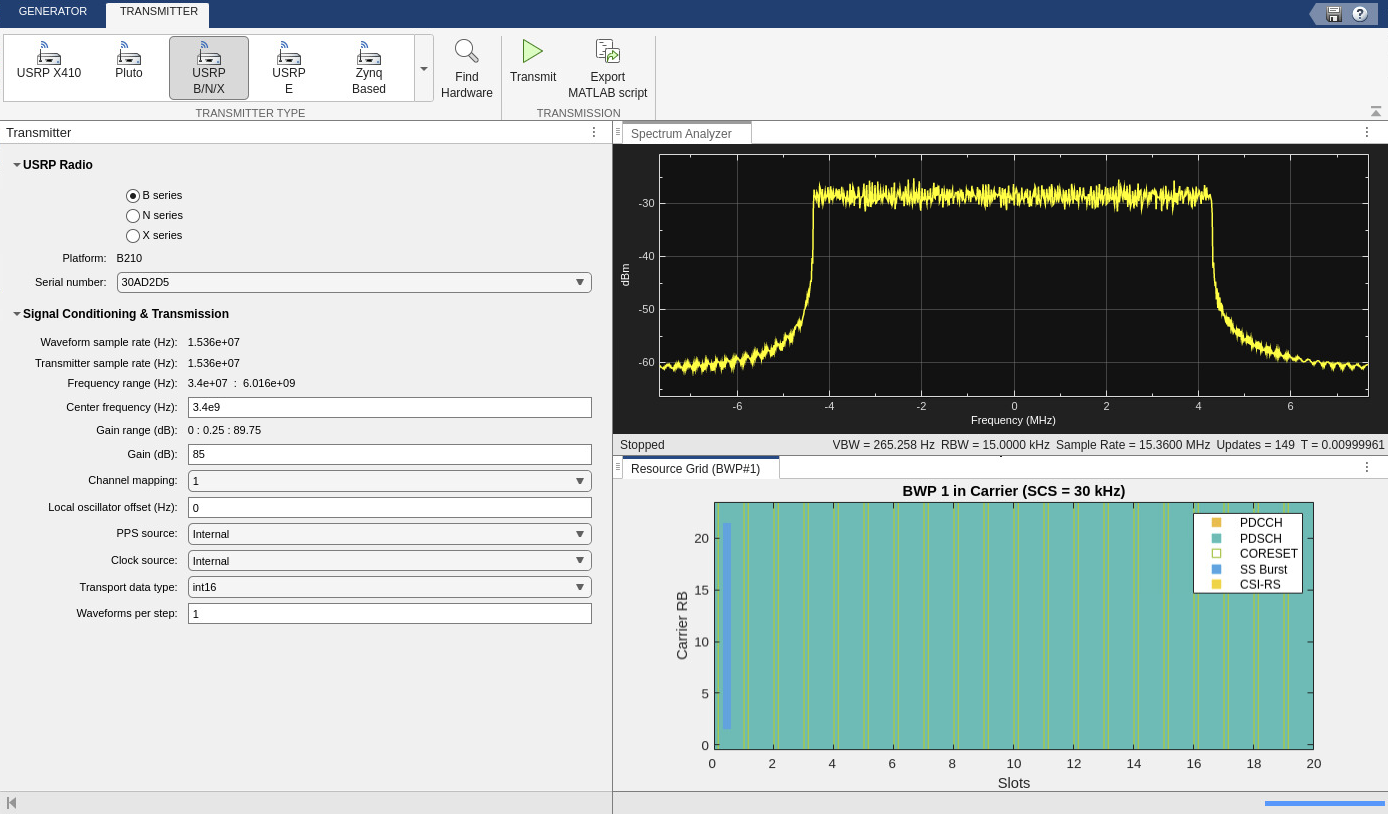

## Capture Transmitted Waveform

**Set Up Receiver Processing Parameters**

Set the downlink waveform parameters used in the app for receiver processing.

rc   = "DL-FRC-FR1-64QAM"; % Reference channel
bw   = "10MHz"; % Channel bandwidth
scs  = "30kHz"; % Subcarrier spacing
dm   = "FDD"; % Duplexing mode
rnti = 0; % Radio network temporary identifier

**Configure SDR Receiver Object**

To capture the waveform that the app continuously transmits, create an `hSDRReceiver` object and then set the object properties.

- Set `rx.CenterFrequency` to `3.4e9`, as specified in the **Transmitter** tab of the app.

- Set `rx.SampleRate` to a value greater than or equal to the **Transmitter sample rate (Hz)** parameter value in the app.

- Set `rx.Gain` to any valid value that provides a successful decode of the captured waveform. Valid values of gain include `'AGC Fast Attack'`, `'AGC Slow Attack'`, or an integer value for the Zynq Based, USRP Embedded, or ADALM-PLUTO radios. USRP radios only support integer values.

rx    = hSDRReceiver("Pluto"); % SDR receiver object
rx.CenterFrequency = 3.4e9; 
rx.SampleRate      = 30.72e6;
rx.Gain            =  60; 

Specify the number of contiguous 5G frames to capture. One frame equates to 10 milliseconds.

framesToCapture    = 1;

% Derived parameters
captureDuration = milliseconds(10)*(framesToCapture+1); % Increase capture frame by 1 to account for a full frame not being captured

**Initiate Waveform Capture**

Initiate a capture of the 5G NR waveform transmitted by the app. 

rxWaveform = capture(rx,captureDuration);

## Establishing connection to hardware. This process can take several seconds.


Plot the power spectral density (PSD) of the received signal.

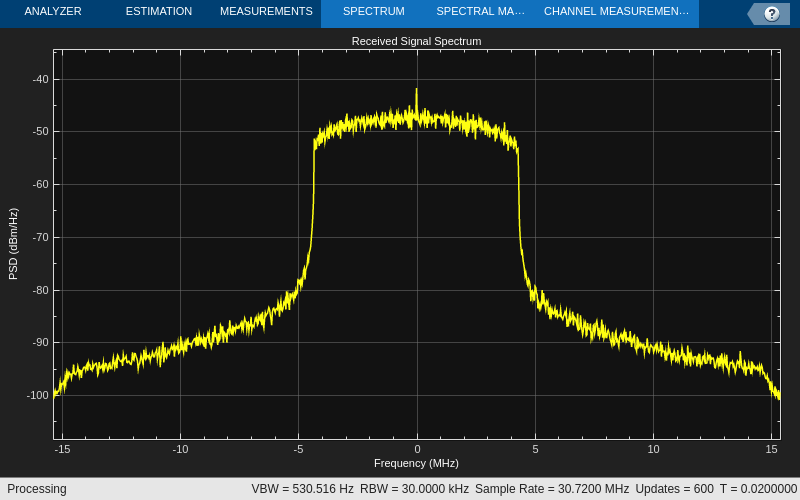

spectrumPlotRx = spectrumAnalyzer;
spectrumPlotRx.SampleRate =  rx.SampleRate;
spectrumPlotRx.SpectrumType = "Power density";
spectrumPlotRx.YLabel = "PSD";
spectrumPlotRx.Title = "Received Signal Spectrum";
spectrumPlotRx(rxWaveform);

## Measure EVM of Received Waveform

Generate and extract a [`nrDLCarrierConfig`](docid:5g_ref#mw_object_nrDLCarrierConfig) object for a specific test model (TM) or fixed reference channel (FRC) using the [`hNRReferenceWaveformGenerator`](matlab:open('./hNRReferenceWaveformGenerator.m')) helper file.

rcwavegen = hNRReferenceWaveformGenerator(rc,bw,scs,dm);
cfgDL = rcwavegen.Config;

Use the [`hNRDownlinkEVM`](matlab:open('./hNRDownlinkEVM.m')) function to analyze the waveform. In this example, the function performs these steps:

- Estimates and compensates for any frequency offset

- Estimates and corrects I/Q imbalance

- Synchronizes the DM-RS over one frame for frequency division duplexing (FDD) or two frames for time division duplexing (TDD)

- Demodulates the received waveform

- Punctures the DC subcarrier component

- Estimates the channel

- Equalizes the symbols

- Estimates and compensates for common phase error (CPE)

- Computes the physical downlink shared channel (PDSCH) EVM

- Computes the physical downlink control channel (PDCCH) EVM

For more information on the `hNRDownlinkEVM` function, see the [EVM Measurement of 5G NR Downlink Waveforms with RF Impairments](docid:5g_ug#mw_c2df9d22-a992-47cc-b21f-ebe4f5de8b5c) example.

Define the configuration settings for the `hNRDownlinkEVM` function.

EVM stats for BWP idx : 1
PDSCH RMS EVM, Peak EVM, slot 1: 3.549 11.660%
PDSCH RMS EVM, Peak EVM, slot 2: 3.269 11.206%
PDSCH RMS EVM, Peak EVM, slot 3: 3.321 14.776%
PDSCH RMS EVM, Peak EVM, slot 4: 3.240 12.982%
PDSCH RMS EVM, Peak EVM, slot 5: 3.269 12.564%
PDSCH RMS EVM, Peak EVM, slot 6: 3.244 12.960%
PDSCH RMS EVM, Peak EVM, slot 7: 3.517 17.604%
PDSCH RMS EVM, Peak EVM, slot 8: 3.446 13.599%
PDSCH RMS EVM, Peak EVM, slot 9: 3.613 20.750%
PDSCH RMS EVM, Peak EVM, slot 10: 3.555 16.538%
PDSCH RMS EVM, Peak EVM, slot 11: 3.430 11.846%
PDSCH RMS EVM, Peak EVM, slot 12: 3.588 11.771%
PDSCH RMS EVM, Peak EVM, slot 13: 3.533 13.308%
PDSCH RMS EVM, Peak EVM, slot 14: 3.375 15.249%
PDSCH RMS EVM, Peak EVM, slot 15: 3.272 11.033%
PDSCH RMS EVM, Peak EVM, slot 16: 3.454 14.465%
PDSCH RMS EVM, Peak EVM, slot 17: 3.297 12.114%
PDSCH RMS EVM, Peak EVM, slot 18: 3.283 10.228%
PDSCH RMS EVM, Peak EVM, slot 19: 3.297 15.695%
PDSCH RMS EVM, Peak EVM, slot 21: 3.521 12.194%
PDSCH RMS EVM, Peak EVM

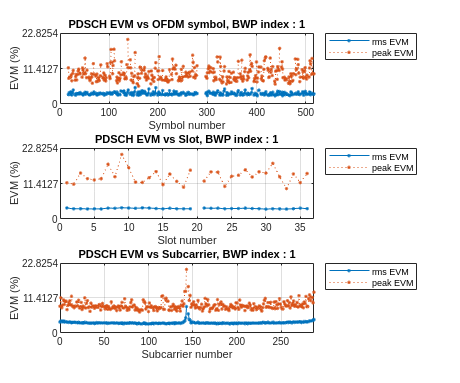

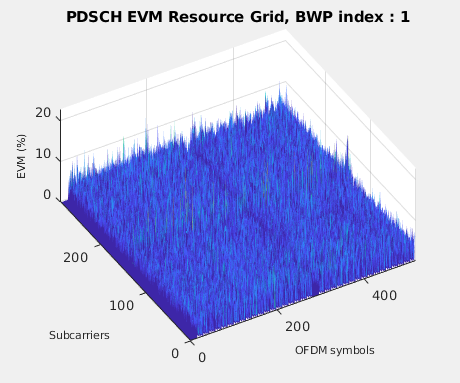

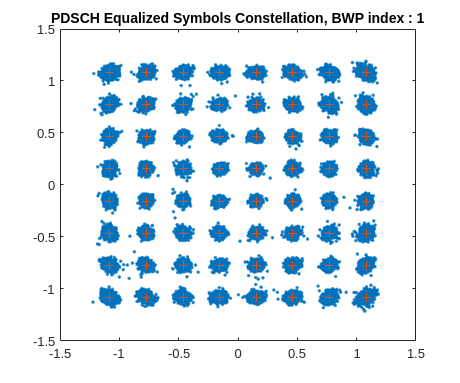

Averaged overall PDSCH RMS EVM: 3.400%
Overall PDSCH Peak EVM = 20.7504%


cfg = struct();
cfg.PlotEVM = true;             % Plot EVM statistics 
cfg.DisplayEVM = true;          % Print EVM statistics
cfg.Label = rc;                 % Set to TM name of captured waveform
cfg.SampleRate = rx.SampleRate; % Use sample rate during capture
cfg.IQImbalance = true;
cfg.TargetRNTIs = rnti;
cfg.CorrectCoarseFO = true;
cfg.CorrectFineFO = true;
cfg.ExcludeDC = true;

[evmInfo,eqSym,refSym] = hNRDownlinkEVM(cfgDL,rxWaveform,cfg);

The output of the `hNRDownlinkEVM` function shows that the demodulation of the received waveform is successful.

*Copyright 2022-2024 The MathWorks, Inc.*